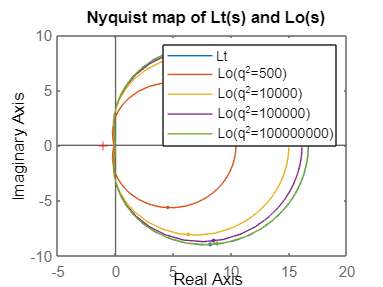

clear; close all;

A=[0 1;-3 -4];
B=[0;1];
Bw=[35;-61];
C=[2 1];
D=0;
Dw=1;
F=[50 10];
R=1;
E=[1 0;0 1];
w=logspace(-2,2);
[z1,p1]=ss2tf(A,B,F,0);
Lt=tf([z1],[p1]);
figure(1)
nyquist(Lt)
title('Nyquist map of Lt(s) and Lo(s) ')
hold on
for q2=[500 10000 100000 100000000]
    Q=q2*B*transpose(B);
    A1=transpose(A);
    B1=transpose(C);
    [P,K,L]=icare(A1,B1,Q,R);
    K=P*B1;
    A2=A-B*F-K*C;
    s = tf('s');
    Lo=F*inv(s*E-A2)*K*C*inv(s*E-A)*B;
    nyquist(Lo,w)
end
legend('Lt', 'Lo(q^2=500)','Lo(q^2=10000)','Lo(q^2=100000)','Lo(q^2=100000000)')

figure(2)
bode(Lt,w)
title('Bode map of Lt(s) and Lo(s)')
hold on
for q2=[500 10000 100000 100000000]
    Q=q2*[0;1]*[0 1];
    A1=transpose(A);
    B1=transpose(C);
    P = icare(A1,B1,Q,R)
    K=P*B1;
    A2=A-B*F-K*C;
    s = tf('s');
    Lo=F*inv(s*E-A2)*K*C*inv(s*E-A)*B;
    bode(Lo,w)
end

P =     0.2441    0.3584
    0.3584   18.0776


P =     0.2497    0.4639
    0.4639   95.1753


P =     0.2500    0.4883
    0.4883  311.2842


P = 	1.0e+03 *

    0.0002    0.0005
    0.0005    9.9950


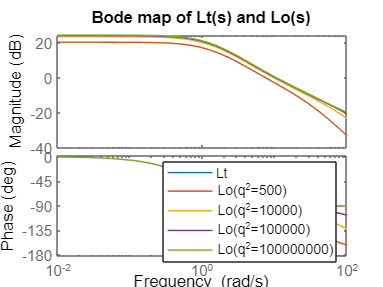

legend('Lt', 'Lo(q^2=500)','Lo(q^2=10000)','Lo(q^2=100000)','Lo(q^2=100000000)')